clc
clear
close all

# Calculates E(x,y,k,theta) from energy balance equation.

The equation to solve is:


$${E\left(x,y,k,\theta \right)}_{n+1} ={E\left(x,y,k,\theta \right)}_n +\delta \left\lbrack -C_g \cos \left(\theta \right)\frac{\mathrm{d}}{\mathrm{d}x}\left(E\right)-C_g \sin \left(\theta \right)\frac{\mathrm{d}}{\mathrm{d}y}\left(E\right)\right\rbrack +S_{\textrm{in}} +S_{\textrm{nl}} -S_{\textrm{ds}}$$


Dimensions of x,y,k,th are m,n,o,p

% prepare log file for commands
dfile=[datestr(now,'mmddyyyy_HHMMSS'),'_FetchLaws.txt'];
diary(dfile);
diary on;

% create output directory for results
parentFolder = fileparts(pwd);
TitanResults = sprintf('%s\\Titan%s', pwd);
if ~exist(TitanResults, 'dir')
  mkdir(TitanResults);
end

file = 1; % 
filec = 1;% file # of coarse grid at same conditions.

## MODEL SET UP

numdays = 1;
% Time = 5;% Wind time step
Time = 10000;% Wind time step
%Tsteps = 6*24*numdays;% Output at each step.
% Tsteps =20;% Output at each step.
Tsteps =2;% Output at each step.
Newdelt = [];

### global constants

kappa = 0.4; % Von-Karman constant
i = sqrt(-1);
kgmolwt = 0.028; %0.029; %gm molecular wt. for air/1000 in Kgm/mol.  Earth
RRR = 8.314; % Universal gas constant in J/K/mol

### grid


$$E\left(x,y,\theta ,k\right)$$



$$x=m;\;y=m;\;\theta =p;\;k=o$$


m = 31; % number of gridpoints in x-direction
n = 15; % number of gridpoints in y-direction

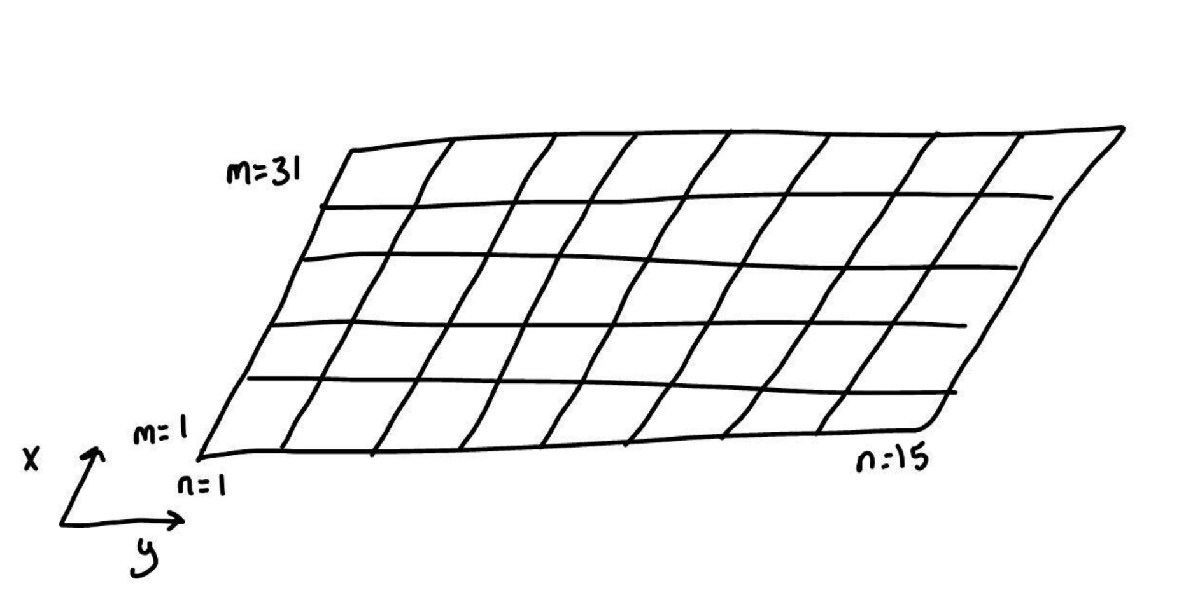

o = 25; % numner of frequency bins usually 20
p=288; % number of angular (th) bins. p must be factorable by 8 for octants.


dr=pi/180;
dthd=360/(p);

delt ($\Delta \mathit{\mathbf{t}}$):

mindelt = 0.0001;%Minimum delt to minimize oscillations of delt to very small values.
maxdelt = 2000.0;%Limit of delt to prevent large values as wind ramps up at startup.

$E^{n+1} =E_s^{n+1} -\Delta \mathit{\mathbf{t}}\left\lbrack \frac{\partial }{\partial x}\left\lbrack \left(c_g \cos \phi +u\right)E^* \right\rbrack +\frac{\partial }{\partial y}\left\lbrack \left(c_g \sin \phi +v\right)E^* \right\rbrack +\frac{\partial }{\partial \phi }\left(\dot{\phi} E^* \right)\right\rbrack$ (B6)

Wind:

gust = 0;% Gust factor applied to wind at each time step
zref = 20;%0.5;% height of reference wind speed; normally at 20m (field) or centerline (tank)
z = 10;%0.3;% height of measured wind speed, m. GRL
wfac = 0.035;%winddrift fraction of Uz. Should be 0.035 of U10m.
UUvec = [0.4:1:3.3];

Wind profile obeys law of wall above liquid surface:

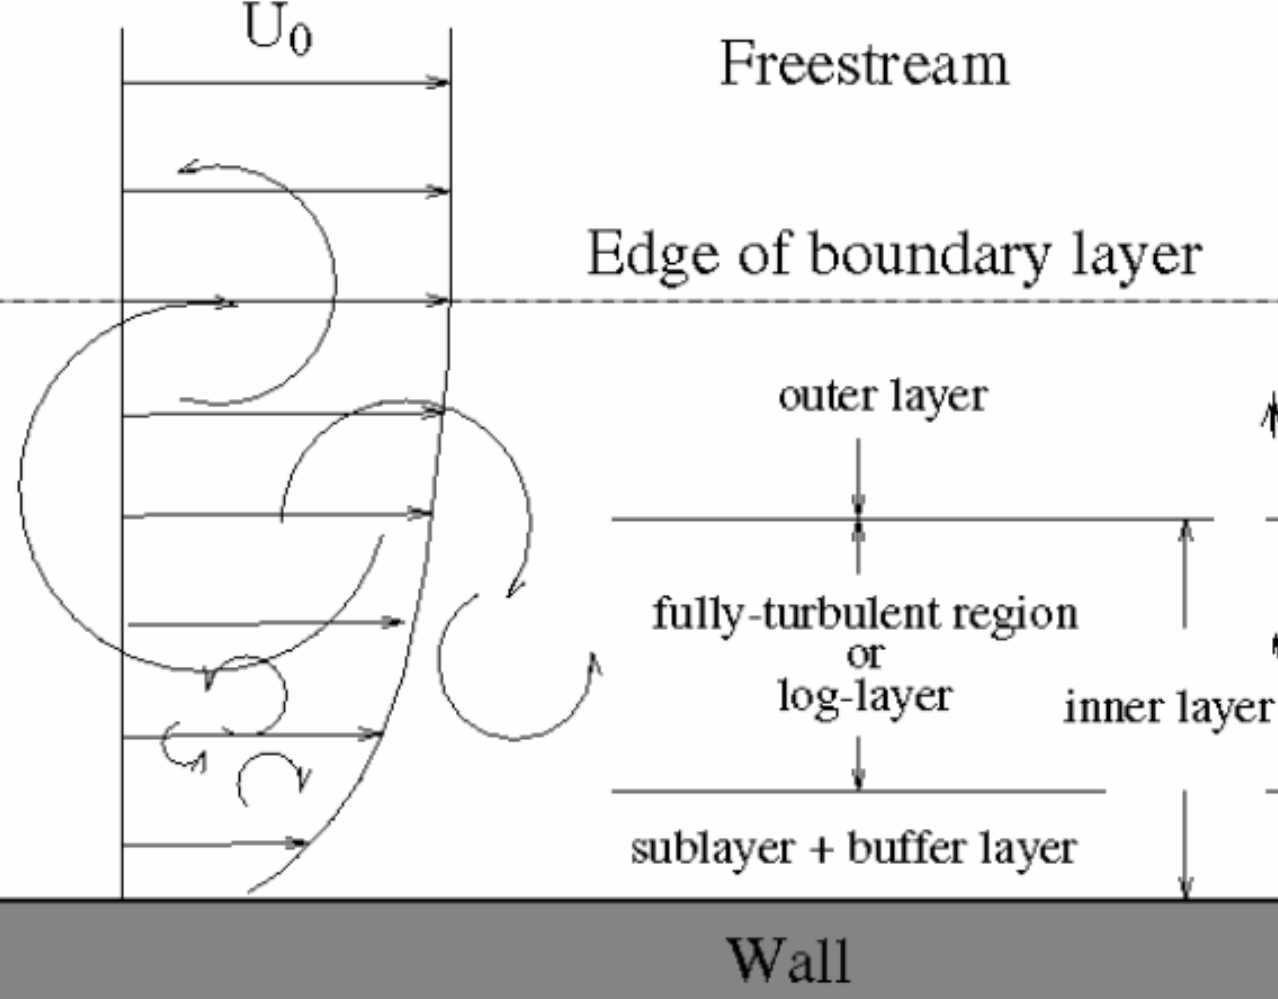

Lake:

long = 29;
lati = 8;% Titan, Punga Mare

Surface Conditions:

% Compute gas density, rhoa
sfcpress = 1.5*[101300];%1.45*[101300];% [Pa].
sfctemp = 92; %273.16 + 23.4; % K.
sfcT = 0.018; % (0.016 from Jordan) 0.074;% surface tension. N/m (0.027 for 75% methane)

Ideal gas law: $\textrm{PV}=\textrm{nRT}$

- 
$$P=\textrm{pressure}$$


- 
$$V=\textrm{volume}$$


- 
$$n=\textrm{amount}\;\textrm{of}\;\textrm{substance}$$


- 
$$R=\textrm{ideal}\;\textrm{gas}\;\textrm{constant}$$


- 
$$T=\textrm{temperature}$$


Densities:

rhoa = sfcpress*kgmolwt/(RRR*sfctemp);% air density.
rhow = 465; %531; %1000;% liquid density. kg/m^3 (550 kg/m^3 for 75% methane)
rhorat=rhoa/rhow; %air-water density ratio.

fluid density ratio, reflects strength of forcing for a given wind: $\frac{\rho_a }{\rho_w }$

Gravity:

g = 1.35; %9.80665; m/s^2

Viscocities:

% nu = 0.003/1e4;%1.78e-6;
nu = 0.0031/1e4; %pure methane %0.017/1e4=pure ethane;%1.78e-6;%Liquid viscosity m^2/s (0.005 for 75% methane)
nua = 0.0126/1e4;%Gas viscosity m^2/s

Wavenumber limits:

kutoff = 1000;%wavenumber cut-off due to KH; maximum = 1000 m^{-1}.
kcg = sqrt(g*rhow/sfcT);% wavenumber of slowest waves -- cap-grav minimum. AAAAAAAAAA

From Airy dispersion: $\omega^2 =g\;k\;\tanh \left(k\;h\right)$

kcgn = 1.0*kcg;%n power min is not shifted wrt kcg.
kcga = 1.15*kcg;%a min is shifted above kcg.

where does information of wavenumber limits come from? 

frequency limits:

f1 = 0.05;
f2=35;

"For computational efficiency (...) frequency of 5 Hz" (Donelan et al. 2012), is there where f1 is coming from?

dlnf=(log(f2)-log(f1))/(o-1);%Set frequencies, Titan 2014/1/3 AAAAAAAAAA %%%SET LIMITS OF SPECTRUM
f = exp(log(f1)+[0:o-1]*dlnf); %%%%%%%
dom = 2*pi*dlnf.*f;
freqs = f;

Frequency bins:

o=length(f)
oa = 7;%top bin advected. Titan (how to adjust run time) !!!!!!!!!!  (make wavelengths [vector wn] at oa 1/20th of the grid spacing)
ol = [1:oa];
os = [oa+1:o];% Bin numbers for long and short frequencies.

% Compute diffusion values in 2 freqs and 2 directions: bf1,bf2,bt1,bt2, such that bf1 + bf2 = 1, and bt1 + bt2 = 1.
dth = 360/p;
bf1 = exp(-15.73*dlnf*dlnf);bf2 = exp(-15.73*4*dlnf*dlnf);% frequencies.
bf1a = bf1/(bf1 + bf2);
bf2 = bf2/(bf1 + bf2);
bf1 = bf1a;

% Compute Snl_fac, i.e. A5 so that downshifting is not fcn of A
A = exp(dlnf);B = A.*A;
fac = bf1.*(1-1/B) + bf2.*(1-1./B.^2);

Snl_fac = ((1.0942/A)^1.9757)/fac;


waveang = ([0:p-1]-p/2+0.5)*dthd*dr;% "+0.5" avoids division by zero in rotation term.

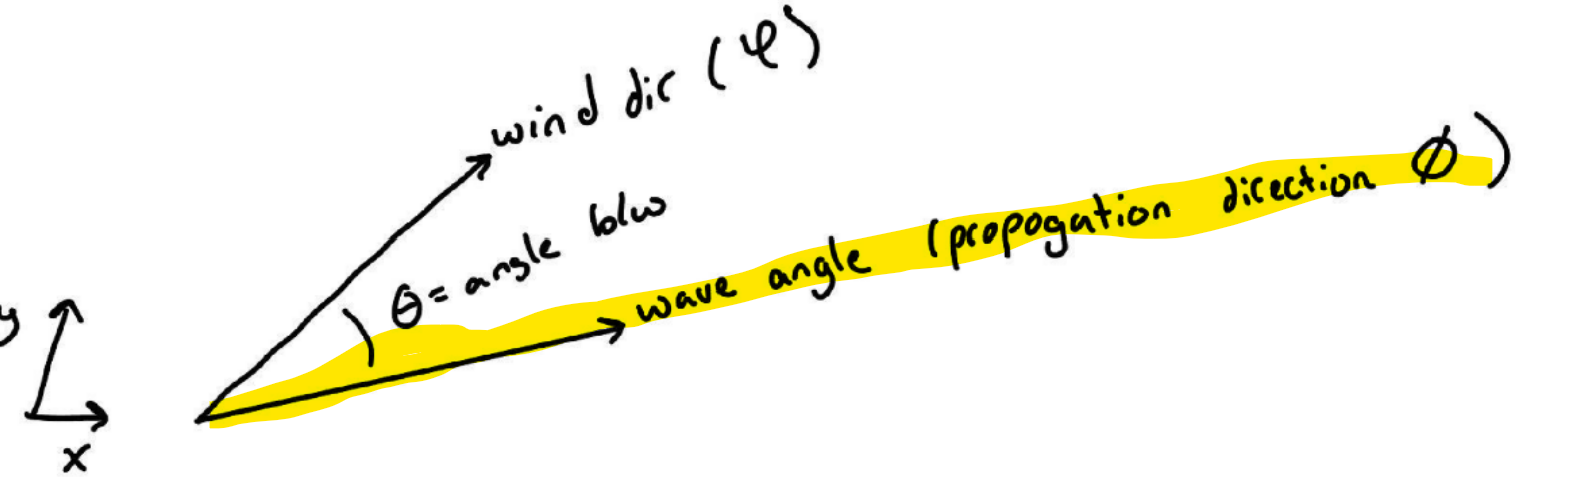

op = [p/2+1:p 1:p/2];% These are opposite directions from the p array for the computation of MSS colinear (with and against) waves.
orm = [p:-1:1];%These are reflected directions for 100% reflection from y-boundaries.

th = ([0:p-1]-p/2+0.5)*dthd*dr;cth=cos(th);sth=sin(th);dth=dthd*dr;% "+0.5" avoids division by zero in rotation term.

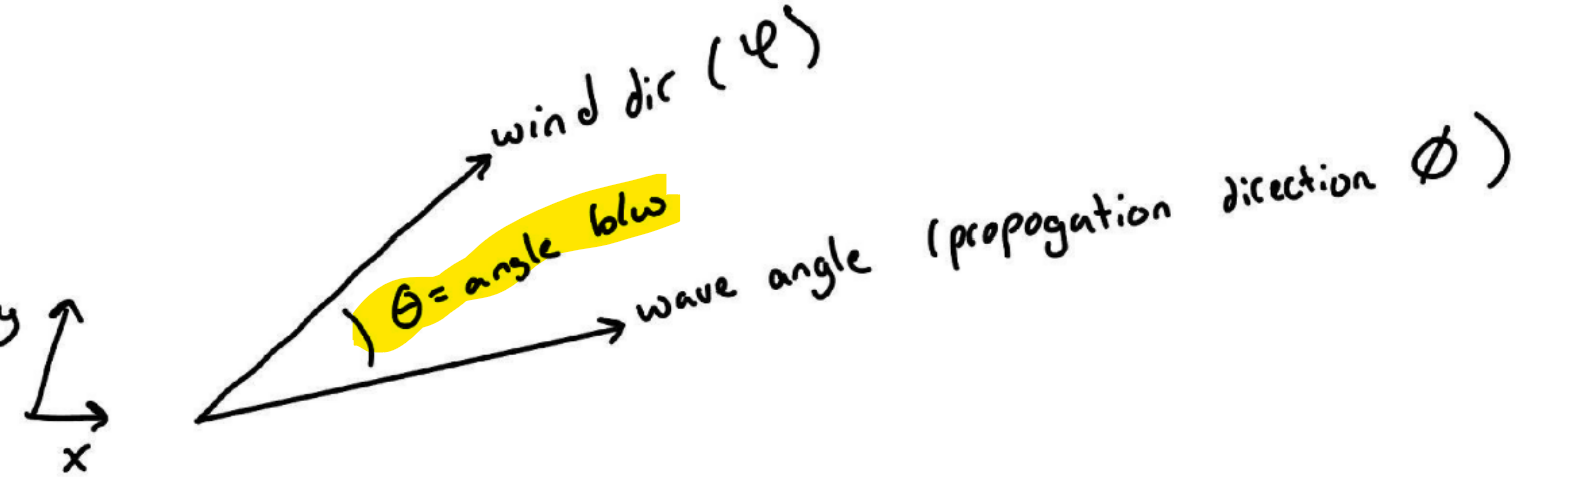

% compute cos^2 for calculation of mss vs direction.
tth = ([0:p-1])*dthd*dr;% angular difference between short waves and longer waves.
cth2 = cos(tth).^2;%figure(1);clf;plot(cth2);grid;

indices for refraction rotation:

cw = ([p 1:p-1]);
ccw = ([2:p 1]);


upwave indices for advective term:

xp = [1 1:m-1];
yp = [1 1:n-1];
xm = [2:m m];
ym = [2:n n];


Index being used for advection (and other stuff?):

cp = find(cth > 0);
cm = find(cth < 0);
sp = find(sth > 0);
sm = find(sth < 0);


cth = repmat(cth,[o 1 m n]);cth=shiftdim(cth,2);
sth = repmat(sth,[o 1 m n]);sth=shiftdim(sth,2);
cth2 = repmat(cth2,[o 1 m n]);cth2=shiftdim(cth2,2);

Lake Geometry:

% % % Set bathymetry -- plane shoal in x.
% D = 20*(1-[1:m]/(m-1));
% D = D'*ones(1,n);

% Set bathymetry -- constant depth.
% D = 0.16;% Ames
D = 100;% Titan
D = D*ones(m,n);% Run 5.

% Add breakwater with gap.
% D([1:21 30:m],36) = 0;

% % Conical island.
%  ccm=36;ccn=26;% coords of centre. Run 22, 16.
% D=zeros(m,n);
% for j1=1:m
%     for j2=1:n
%   D(j1,j2)=2*abs((j1-ccm) + i*(j2-ccn))-9;%Run 21, 20 etc.
% % D(j1,j2)=0.2*abs((j1-ccm) + i*(j2-ccn))-0.9;%Run 21, 20 etc.
% end
% end
% % Conical island end.

% turn all negative depths to zero -- UGS
j12=find(D<=0);
D(j12)=0;


% Impose depth limits. % $$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$ 2010/9/24-START


% jj = find (D > 0 & D < 0.4);D(jj)=0.4;% Limit shallow water. 2010/02/25
jj = find (D < 0);
D(jj)=0;% Limit land elevations to 0 to avoid dD/dx, dD/dy errors in refraction calculation. 2010/03/9

%@@@@@@@@@@@@@@@@@@@@@ Set array boundary depths to 0. 2010/03/04.  -- why do boundary depths need to be zero? UGS
D(:,1)=0;%If lateral boundaries are absorptive.
D(1,:)= 0;
D(:,end)=0;%If lateral boundaries are absorptive.
D(end,:)=0;


[xplot,yplot] = meshgrid(1:m,1:n);
figure;
surf(xplot',yplot',D,'EdgeColor','k')
myc = colorbar;
myc.Label.String = 'Liquid Depth [m]';
title('Lake Model Bathymetry')
% Impose depth limits. % $$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$ 2010/9/24-END

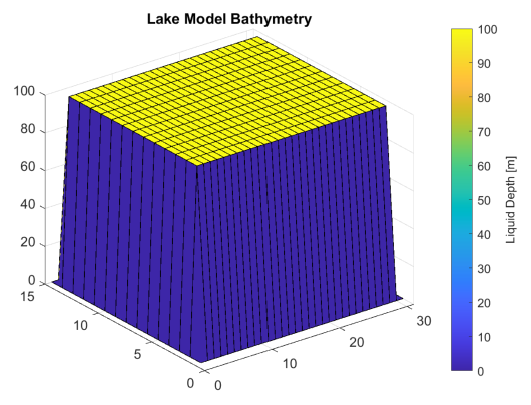

Constant coefficient (fractions applied to terms from fitting with experiment/observations):

%###################################### Changed to 2000 2010/02/17. This
%section moved up -- define facs. Note SDs_fac change.  AAAAAAAAAA
%section moved up -- define facs. Note SDs_fac change.  AAAAAAAAAA
mss_fac = 240;% MSS adjustment to Sdiss. 2000 produces very satisfactory overshoot, 400 does not. 2009/12/15, Run 986
% Snl_fac = 3.5;% fraction of Sdiss that goes to longer wavenumbers.$$$$$$$$$$$$$2010/11/10. X10
% Snl_fac = 4.3;% fraction of Sdiss that goes to longer wavenumbers.$$$$$$$$$$$$$2010/11/10. X11
Sds_fac = 1.0;% This is fac with variable power nnn in Sds.
Sdt_fac = 0.001;
Sbf_fac = 0.002;% Select for bottom roughness. 0.004 is for smooth sandy bottom as in GOM.



wn(:,:,:) = ones(m,n,o);
nnn(:,:,:) = ones(m,n,o);
ann(:,:,:) = ones(m,n,o);
for jm = 1:m
    for jn = 1:n
        if D(jm,jn) > 0;
            wn(jm,jn,:) = WAVEKgT(f,D(jm,jn),g,sfcT,rhow,1e-4);% 2013/12/16. -- wave number UGS
            nnn(jm,jn,:) = 1.2 + 1.3*(abs(2 - (1+3*(wn(jm,jn,:)./kcgn).^2)./(1+(wn(jm,jn,:)./kcgn).^2)).^2.0);% Power of Sds
            ann(jm,jn,:) = 0.04 + 41.96*(abs(2 - (1+3*(wn(jm,jn,:)./kcga).^2)./(1+(wn(jm,jn,:)./kcga).^2)).^4.0);% Power of Sds
        end
    end
end

% reshape the matrix
wn = repmat(wn,[1 1 1 p]);
nnn = repmat(nnn,[1 1 1 p]);
ann = repmat(ann,[1 1 1 p]);
nnn = (2.53/2.5).*nnn;
nnninv = 1./nnn;%

Depth = D;
D=repmat(D,[1 1 o p]);

Set up geographic deltas

Delx = 1000.0;% m. Titan
Dely = 1000.0;% m. Titan
dely = Dely*ones(m,n,o,p);
delx = Delx*ones(m,n,o,p);

ocean currents (no currents for now):

Uer=0*D + 0.0;% Eastward current, m/s
Uei=0*D + 0.0;% Northward current, m/s

f=repmat(f',[1 p m n]);
f=shiftdim(f,2);
dom=repmat(dom',[1 p m n]);
dom=shiftdim(dom,2);

c=(2*pi*f)./wn;
c(D<=0) = 0;Cg=zeros(size(c));
Cg(D>0) = c(D>0)./2.*(1 + 2*wn(D>0).*D(D>0)./sinh(2*wn(D>0).*D(D>0)) + 2*sfcT.*wn(D>0)./rhow./(g./wn(D>0) + sfcT.*wn(D>0)./rhow));%Group velocity for all waves.

dwn = ones(m,n,o,p);
dwn(D>0)=dom(D>0)./abs(Cg(D>0));%$$$$$$$$$$$$$$$$$$$$$$ADDED to avoid NaNs.  2010/09/24.

Cg(D<=0) = 0;

l2=abs(c)./f/2;%wavelength/2;
lz=abs(c)./f/2/pi;% wavelength/2/pi: kz = 1 for drift current action;

%########################################################### Added 2010/02/17;
% Set l2, lz > zref equal to zref; -- WHY? UGS
l2(l2 > zref) = zref;
lz(lz > zref) = zref;
%########################################################### Added 2010/02/17;


E = zeros(m,n,o,p); % initializing the energy term in x,y,k,theta with zeros UGS

% Set delt by Courant condition.
Ccg = Cg + Uer.*cth + Uei.*sth;

cgmax = max(max(max(max(Cg))));
mindelx = min(squeeze(delx(1,:,1,1)));
delt = 0.7 * mindelx / cgmax;% advection limited Courant condition.
waveang = repmat(waveang,[o 1 m n]);
waveang=shiftdim(waveang,2);

eval(['save Titan/Titan_',int2str(file),'_ref m n o p freqs f wn dwn D Uei Uer Cg c delx dely dthd waveang'])

file = file - 1;

% HERE IS WHERE THE HEART OF THE CALCULATIONS START : ---UGS
tic

sumt = 0;
tplot = -1;
%  for UU = [7 8 12 20 30]./10;% Run several different wind speeds for fetch laws. Titan
%  for UU = [8 12 20 30]./10;% Run several different wind speeds for fetch laws. Titan
%  for UU = [4 5 6]./10;% Run several different wind speeds for fetch laws. Titan
% for UU = [4 5 6 7 8 12 20 30]./10;% Run several different wind speeds for fetch laws. Titan
% for UU = [7:2:30]./10;% Run several different wind speeds for fetch laws. Titan
%UUvec = [4:1:20]./10;
%UUvec = linspace(4,30,100)./10;
%for UU = UUvec;% Run several different wind speeds for fetch laws. Titan

idx = 1; % for frame for gif

for iii=1:numel(UUvec)
    UU = UUvec(iii);
    file = file + 1;
    
    U = UU*ones(m,n); % set U everywhere in x-y plane to UUvec(iii) UGS
    windir = 0*ones(m,n); % set wind direction to zero  everywhere in x-y plane UGS
    %   windir = 45*dr*ones(m,n);
    windir=repmat(windir,[1 1 o p]); % reshape wind direction matrix for some reason UGS
    
    
    U_z = U + 0.005;% avoid division by zero. 
    
    Cd=1.2*ones(size(U)); % coefficient of friction? UGS

    uj = find(U > 11);
    Cd(uj)=.49 +.065*U(uj); % where is this from? UGS
    Cd=Cd/1000;% Large and Pond for starters.
    
    modt = 0;
    
    
    % % Load E from coarse grid at upstream depth.
    % eval(['load d:/donb/field/mod_',int2str(filec),'_',int2str(UU),'_',int2str(36)])
    % E_coarse = E(26,3,:,:);
    %  E = 0*E;%@@@@@@@@@@@@@@@@@ 2010/03/08 to allow starting from cont == 1;
    
    % % size(E_coarse)
    % E_coarse = repmat(E_coarse,[1,n,1,1]);
    % % size(E_coarse)
    %
    
    %   % Currents from ocean model
    Uer=0*D + 0.0;% Eastward current, m/s % repeated above (need to condense)
    Uei=0*D + 0.0;% Northward current, m/s % repeated above (need to condense)
    
    slostart = 1;


    for t=1:Tsteps
        Newdelt = [];
        
        sumt = 0;
        tplot = - 1;
        

        while ((Time - sumt) > 0)
            
            if gust > 0
                % %######################################### Add random wind 2010/02/18
                U = U.*(1+gust*randn(size(U)));% Randomize wind speed
                % %######################################### Add random wind 2010/02/18
            end


            tplot = tplot + 1;
            explim = 0.1;
            delt = 0.7 * mindelx / cgmax;% advection limited Courant condition.
            

            Ul=real(U_z.*sqrt(Cd));
            Ustar = Ul;
            U_10 = 2.5*Ul.*log(10/z) + U_z; % law of wall UGS
            ustarw = Ustar .* sqrt(rhorat); % shear stress? UGS
            
            Ul = repmat(Ul,[1 1 o p]);
            U = repmat(U_z,[1 1 o p]);
            Ul=2.5*Ul.*log(l2/z)+U;
            clear Cd
            
            ustw = repmat(ustarw,[1 1 o p]);
            Ud = - ustw./kappa.*log(lz/z);
            %     Ud = 0*Ud;
            
            %calculate wind input as a fraction of stress. !!!! CALCULATION FOR WIND STRESS HERE UGS
            Ul(D>0)=abs(Ul(D>0).*cos(windir(D>0)-waveang(D>0))-c(D>0)-Ud(D>0).*cos(windir(D>0)-waveang(D>0))-Uer(D>0).*cth(D>0)-Uei(D>0).*sth(D>0))...
                .*(Ul(D>0).*cos(windir(D>0)-waveang(D>0))-c(D>0)-Ud(D>0).*cos(windir(D>0)-waveang(D>0))-Uer(D>0).*cth(D>0)-Uei(D>0).*sth(D>0));% Ul is now (Ucos(th)-c-drift*cos(phi)).^2.
            
            
            % % Adjust input to lower value when waves overrun the wind.
            %%      as wave speed approaches wind speed, energy extraction becomes less efficient UGS
            Ula = Ul; 
            Ul = 0.11*Ul; % where is this fraction from? UGS
            fij=find(Ul<0);
            Ul(fij) = Ula(fij)*0.03;% where is this fraction from? UGS
            clear fij;% Field scale (Donelan et al, 2012). 0.135 in Lab AAAAAAAA
            fij = find(cos(windir-waveang)<0);% Waves against wind.
            Ul(fij) = Ula(fij)*0.015;% Waves against wind.
            clear fij;% Waves against wind.

            %% !!!! INPUT TO ENERGY SPECTRUM HERE UGS 
            Sin = zeros(size(Ul));
            Sin(D>0)=rhorat*(Ul(D>0).*2*pi.*f(D>0).*wn(D>0)./(g+sfcT.*wn(D>0).*wn(D>0)./rhow)) ;
            % limits energy going into spectrum once waves outrun wind
            Heavyside = ones(size(E));
            Heavyside(Sin < 0 & E < 1e-320) = 0;
            Sin = Heavyside.*Sin;
            clear Ul Heavyside Ula
            
            %########################################################## Added 2010/02/17.
            % Set Sin = 0 on land boundaries to avoid newdelt --> 0.
            Sin(D<=0) = 0;
            %########################################################## Added 2010/02/17.
            
        

    
            for tj = 1:p
                short(:,:,:,tj) = sum(E.*cth2(:,:,:,rem([1:p]-tj+p,p)+1),4)*dth;
            end
            short = (cumsum((wn.^3.*short.*dwn),3)-wn.^3.*short.*dwn);
            

            % Calculate turbulent dissipation: Sdt = 4 nu_t k^2.
            Sdt(:,:,:,:) = repmat(Ustar,[1 1 o p]);
            clear Ustar
            Sdt = Sdt_fac*sqrt(rhorat).*Sdt.*wn;
            Sbf = zeros(m,n,o,p);
            Sbf(D>0) = Sbf_fac*wn(D>0)./sinh(2*wn(D>0).*D(D>0));
            Sds = zeros(size(Sin));
            Sds(D>0)=abs(ann(D>0)*2*pi.*f(D>0).*(1+mss_fac*short(D>0)).^2.*(wn(D>0).^4.*E(D>0)).^(nnn(D>0))) ;%AAAAAA changed to LH p 712. vol 1 6/2014.
            
            %########################################################## Added 2010/02/17.
            % Set Sds = 0 on land boundaries to avoid newdelt --> 0.
            %@@@@@@@@@@@@@@@@@@@@@ 2010/02/27.
            Sds(D<=0) = 0;
            %########################################################## Added 2010/02/17.
            

            % Spread Snl to 2 next longer wavenumbers exponentially decaying as distance from donating wavenumber.$$$$$$$$$$$$$ 2011/03/25 START
            Snl = zeros(m,n,o,p);
            Snl(:,:,1:end-1,:) = bf1*Snl_fac*(Sds(:,:,2:end,:).*E(:,:,2:end,:).*wn(:,:,2:end,:).*dwn(:,:,2:end,:));
            Snl(:,:,1:end-2,:) = Snl(:,:,1:end-2,:) + bf2*Snl_fac*(Sds(:,:,3:end,:).*E(:,:,3:end,:).*wn(:,:,3:end,:).*dwn(:,:,3:end,:));
            % Spread Snl to 2 next longer wavenumbers exponentially decaying as distance from donating wavenumber.$$$$$$$$$$$$$ 2011/03/25 END
            
            Snl(:,:,:,:) = Snl(:,:,:,:)./(wn(:,:,:,:).*dwn(:,:,:,:));%Renormalize to receiving wavenumber and bandwidth.
            Snl(:,:,:,:) = Snl(:,:,:,:) - Snl_fac*(Sds(:,:,:,:).*E(:,:,:,:));% Remove downshifted energy.%2011/6/21%
            Snl(D <= 0) = 0;
            % Integrate source functions.
            Sds_wc = Sds;% Keep whitecapping (wc) only dissipation for calculating snl growth.
            Sds(D>0) = coth(0.2*wn(D>0).*D(D>0)).*Sds(D>0) + Sdt(D>0) + Sbf(D>0) + 4*nu*wn(D>0).^2;% Add viscous, turbulent and plunging dissipation after calculation of Snl. 2011/05/16 @@@@@@@@@@@@@@@@
            % E0 = E;E0(E<1e-5) = 1e5;
            % aa = Sin(:,:,ol,:) - Sds(:,:,ol,:) + Snl(:,:,ol,:)./E0(:,:,ol,:);aa = aa(D(:,:,ol,:)>0);aa = max(abs(aa(:)));%
            

            aa = Sin(:,:,ol,:) - Sds(:,:,ol,:);
            aa = aa(D(:,:,ol,:)>0);
            aa = max(abs(aa(:)));%
            aaa = explim;
            
            if isnan(aa) == 1; % if the dissipation term is zero then do something to aa term whatever that is
                aa = aaa/maxdelt;
            end
            newdelt = max([aaa/aa mindelt]);
            newdelt=min([newdelt maxdelt (Time-sumt) delt]);% newdelt = delt to give max of 50% growth or decay. $$$$$$$$$$$ Changed 0.4 to 0.2 on 2010/11/23.
            
            % Newdelt = [Newdelt newdelt];
            sumt = sumt + newdelt; 
            modt = modt + newdelt;
            

            fac_exp=(Sin(:,:,ol,:) - Sds(:,:,ol,:));%$$$$$$$$$$$$$$$$
            
            %% !!!! ENERGY SPECTRUM RESULT UGS
            E1 = zeros(size(E));
            E1(:,:,ol,:) = E(:,:,ol,:).*exp(newdelt*fac_exp);% Long waves.
            
            
            E1(:,:,ol,:) = E1(:,:,ol,:) + newdelt*Snl(:,:,ol,:);% 1.0656 is exp(0.4)/1.4
            cath = ones(size(Sds));
            cath(D>0)=coth(0.2*wn(D>0).*D(D>0));
            E2(:,:,:,:) = zeros(m,n,o,p);
            fij = find((Sin(:,:,:,:) - 4*nu*wn(:,:,:,:).^2 - Sdt(:,:,:,:) - Sbf(:,:,:,:)) > 0);
            E2(fij) = wn(fij).^(-4).*((Sin(fij)-4*nu*wn(fij).^2 - Sdt(fij) - Sbf(fij))./(cath(fij).*ann(fij)*2*pi.*f(fij).*(1+mss_fac*short(fij)).^2)).^(nnninv(fij));%AAAAAAA Changed to LH p.712, vol 1. 19/6/2014.
            E2(D<=0) = 0;
            E1(D<=0) = 0;
            E2(E2<0) = 0;
            E1(E1<0) = 0;
            
            E1(:,:,os,:) = E2(:,:,os,:);
            
            clear E2
            
            %$$$$$$$$$$$$$$$$$$$$$$ Display max(mss); should be < 0.01.  2010/11/01
            % max_mss = max(max(max(max(short))))
            
            % clear short
            E1=real(E1);
            ji=find(E1 < 0);
            E1(ji)=0;
            E1(D <= 0)=0;%@@@@@@@@@@@@@@@@@@@@@ 2010/02/27.
            E(D <= 0)=0;%@@@@@@@@@@@@@@@@@@@@@ 2010/02/27.
            % E=(E+E1)/2;% $$$$$$$$$$$$$$$$$$$ 2010/09/28.Replace with following 2 lines
            E(:,:,os,:) = E1(:,:,os,:);
            E(:,:,ol,:) = (E(:,:,ol,:)+E1(:,:,ol,:))/2;
            
            

            % Compute advection -- move this into individual function call
            advect=zeros(m,n,o,p);
            Ccg = Cg + Uer.*cth + Uei.*sth;
            

            
            % Upwave advection with account taken of varying delx and dely. @@@@@@@@@@@@@@@@@@@@ added 2010/03/02.
            advect(:,:,ol,cp)=advect(:,:,ol,cp)+(Ccg(:,:,ol,cp).*cth(:,:,ol,cp).*E(:,:,ol,cp).*dely(:,:,ol,cp)...
                - Ccg(xp,:,ol,cp).*cth(xp,:,ol,cp).*E(xp,:,ol,cp).*dely(xp,:,ol,cp))...
                ./((dely(xp,:,ol,cp) + dely(:,:,ol,cp)).*(delx(xp,:,ol,cp) + delx(:,:,ol,cp)))*4;
            
            advect(:,:,ol,cm)=advect(:,:,ol,cm)+(Ccg(xm,:,ol,cm).*cth(xm,:,ol,cm).*E(xm,:,ol,cm).*dely(xm,:,ol,cm)...
                - Ccg(:,:,ol,cm).*cth(:,:,ol,cm).*E(:,:,ol,cm).*dely(:,:,ol,cm))...
                ./((dely(:,:,ol,cm) + dely(xm,:,ol,cm)).*(delx(:,:,ol,cm) + delx(xm,:,ol,cm)))*4;
            
            advect(:,:,ol,sp)=advect(:,:,ol,sp)+(Ccg(:,:,ol,sp).*sth(:,:,ol,sp).*E(:,:,ol,sp).*delx(:,:,ol,sp)...
                - Ccg(:,yp,ol,sp).*sth(:,yp,ol,sp).*E(:,yp,ol,sp).*delx(:,yp,ol,sp))...
                ./((dely(:,yp,ol,sp) + dely(:,:,ol,sp)).*(delx(:,yp,ol,sp) + delx(:,:,ol,sp)))*4;
            
            advect(:,:,ol,sm)=advect(:,:,ol,sm)+(Ccg(:,ym,ol,sm).*sth(:,ym,ol,sm).*E(:,ym,ol,sm).*delx(:,ym,ol,sm)...
                - Ccg(:,:,ol,sm).*sth(:,:,ol,sm).*E(:,:,ol,sm).*delx(:,:,ol,sm))...
                ./((dely(:,:,ol,sm) + dely(:,ym,ol,sm)).*(delx(:,:,ol,sm) + delx(:,ym,ol,sm)))*4;
            
            

            E1(:,:,ol,:) = E1(:,:,ol,:) - newdelt*advect(:,:,ol,:);% Need compute only "ol" frequencies here.@@@@@@@@@@@@@@ 2010/03/02.
            
            E1(D <= 0)=0;%@@@@@@@@@@@@@@@@@@@@@ 2010/02/27.
            
            %@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@ added 2010/03/10.
            E1=real(E1);
            ji=find(E1 < 0);
            E1(ji)=0;
            E1(D <= 0)=0;%@@@@@@@@@@@@@@@@@@@@@ 2010/02/27.
            

            % Compute refraction including wave-current interaction. %$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$ 2010/09/24-START
            Crot(:,:,ol,:)=(c(xm,:,ol,:)-c(xp,:,ol,:)).*sth(:,:,ol,:)./(delx(xm,:,ol,:)+delx(xp,:,ol,:))...
                -(c(:,ym,ol,:)-c(:,yp,ol,:)).*cth(:,:,ol,:)./(dely(:,ym,ol,:)+dely(:,yp,ol,:));
            
            % Determine if rotation is clockwise or counter clockwise. @@@@@@@@@@@@@@@@@@@@@@@@@@ 2010/03/09.
            Crotcw = zeros(size(Crot));Crotccw = zeros(size(Crot));
            Crotccw(Crot>0) = Crot(Crot>0);
            Crotcw(Crot<0) = Crot(Crot<0);
            jj = find (Crotccw > dth/newdelt);Crotccw(jj) = dth/newdelt;
            jj = find (Crotcw < -1*dth/newdelt);Crotcw(jj) = -1*dth/newdelt;
            E1(:,:,ol,cw) = E1(:,:,ol,cw) - newdelt*Crotcw(:,:,ol,:).*E(:,:,ol,:)/dth;
            E1(:,:,ol,:) = E1(:,:,ol,:) + newdelt*Crotcw(:,:,ol,:).*E(:,:,ol,:)/dth;
            E1(:,:,ol,ccw) = E1(:,:,ol,ccw) + newdelt*Crotccw(:,:,ol,:).*E(:,:,ol,:)/dth;
            E1(:,:,ol,:) = E1(:,:,ol,:) - newdelt*Crotccw(:,:,ol,:).*E(:,:,ol,:)/dth;
            clear Crotccw Crotcw Crot
            

            % Compute refraction including wave-current interaction. %$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$ 2010/09/24-END
            
            ji=find(E1 < 0);
            E1(ji)=0;
            E1(D <= 0)=0;%@@@@@@@@@@@@@@@@@@@@@ 2010/02/27.
            E=real(E1);
            
            enan = find(isnan(E)==1);
            E(enan) = 0;%$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$ 2010/10/19
            E1 = E;%$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$$ 2010/10/19
            
            
            % % Make all land points = 0 and upstream values equal to coarse grid;
            %
            %  E(:,1,:,:)=0;%If lateral boundaries are absorptive.
            % % E(1,:,:,:)= E_coarse;
            % E(1,:,:,:)= 0;
            %  E(:,end,:,:)=0;%If lateral boundaries are absorptive.
            % E(end,:,:,:)=0;
            E(D <= 0)=0;%@@@@@@@@@@@@@@@@@@@@@ 2010/02/27.
            
            % % Apply K-H suppression here.
            % E(:,:,obb,:) = 0.0;
            
            
            % Set wave paddle spectrum.
            % paddle = zeros(m,n,o,p);paddle(1,:,6,19)=1;
            
            % Make boundaries reflective for tanks.
            % E(:,1,:,:)= E(:,2,:,orm);
            % E(:,n,:,:)= E(:,n-1,:,orm);
            % E(1,:,:,:)= E(2,:,:,orm);
            % E(m,:,:,:)= E(m-1,:,:,orm);
            % E(1,:,:,:)=E(1,:,:,:)+paddle(1,:,:,:);
            
            E(D<=0)=0;% Land values.
            

            % Compute form stress spectrum.
            tauE = sum(wn.*E.*Sin.*cth./c,4)*dthd*dr;
            tauN = sum(wn.*E.*Sin.*sth./c,4)*dthd*dr;
            % Add wind speed dependent tail of slope, "mtail" pinned to the highest wavenumber, "wnh".
            mtail = 0.000112*U_10.*U_10 - 0.01451.*U_10 - 1.0186;
            wnh = squeeze(wn(:,:,o,1));
            
            tauE = rhow*(sum((g+sfcT.*squeeze(wn(:,:,:,1)).^2./rhow).*squeeze(dwn(:,:,:,1)).*tauE,3) + ...
                (g+sfcT.*squeeze(wn(:,:,o,1)).^2./rhow).*squeeze(tauE(:,:,o)).*wnh.^(-mtail).*(kutoff.^(mtail+1)-wnh.^(mtail+1))./(mtail+1));
            tauN = rhow*(sum((g+sfcT.*squeeze(wn(:,:,:,1)).^2./rhow).*squeeze(dwn(:,:,:,1)).*tauN,3) + ...
                (g+sfcT.*squeeze(wn(:,:,o,1)).^2./rhow).*squeeze(tauN(:,:,o)).*wnh.^(-mtail).*(kutoff.^(mtail+1)-wnh.^(mtail+1))./(mtail+1));
            % tauE = rhow*(sum((g+sfcT.*squeeze(wn(:,:,:,1)).^2./rhow).*squeeze(dwn(:,:,:,1)).*tauE,3));
            % tauN = rhow*(sum((g+sfcT.*squeeze(wn(:,:,:,1)).^2./rhow).*squeeze(dwn(:,:,:,1)).*tauN,3));
            
            Cd = abs(tauE + i*tauN)./rhoa./(U_z.^2); % from definition of shear stress and law of the wall UGS
            Cdf = Cd;
            Ustar_smooth = smooth_nu((1-wfac)*U_z(:),z,nua);
            Ustar_smooth = reshape(Ustar_smooth,m,n);% Surface current; 3.5% cm/s. GRL5 (friction velocity for hydraulically smooth interface)
            
            Ustar_smooth = (Ustar_smooth./U_z).^2;
            Cds =  Ustar_smooth;
            
            Ustar_smooth = U_z.^2.*(0.3333*Ustar_smooth + 0.6667*(Ustar_smooth.^2)./(Ustar_smooth + Cd));%Feb 22, 2012
            tauE = tauE + rhoa*Ustar_smooth.*cos(squeeze(windir(:,:,1,1))); % shear stress to east UGS
            tauN = tauN + rhoa*Ustar_smooth.*sin(squeeze(windir(:,:,1,1))); % shear stress to north UGS
            clear Ustar_smooth;
            Cd = abs(tauE + i*tauN)./rhoa./(U_z.^2);
            

            
            
            if rem(tplot,10) == 0% plot every 10th time step. 
                
                % diagnostic plot
                figure(16);clf;semilogx(squeeze(wn(2,lati,:,p/2)),squeeze(sum(wn([2:4:m],lati,:,:).*E([2:4:m],lati,:,:),4)*dthd*dr)','*-');grid on
                title(['Omni directional wavenumber spectra along latitude ',num2str(lati),'. Time = ',num2str(modt/3600),' Hours'])
                pause(2)
                
                figure(202);clf;subplot(321);plot(Cd(:,lati).*(U_z(:,lati)./U_10(:,lati)).^2,'.-');% Drag coefficient vs fetch
                title('Drag coefficient')
                grid on
                %pause(2)
                figure(202);hold on;subplot(322);semilogx(squeeze(wn(long,lati,:,10)),squeeze(sum(wn(long,lati,:,:).^2.*Sin(long,lati,:,:).*E(long,lati,:,:),4))*dthd*dr,'*-');
                title('k*Sin');grid on
                %pause(3)
                figure(202);hold on;subplot(323);semilogx(squeeze(wn(long,lati,:,10)),squeeze(sum(wn(long,lati,:,:).^2.*Sds(long,lati,:,:).*E(long,lati,:,:),4))*dthd*dr,'*-');
                figure(202);hold on;subplot(323);semilogx(squeeze(wn(long,lati,:,10)),squeeze(sum(wn(long,lati,:,:).^2.*Sdt(long,lati,:,:).*E(long,lati,:,:),4))*dthd*dr,'*-g');
                figure(202);hold on;subplot(323);semilogx(squeeze(wn(long,lati,:,10)),squeeze(sum(wn(long,lati,:,:).^2.*Sbf(long,lati,:,:).*E(long,lati,:,:),4))*dthd*dr,'*-r');
                title('k*Sds(b), k*Sdt(g), k*Sbf(r)');grid on
                %pause(3)
                figure(202);hold on;subplot(324);semilogx(squeeze(wn(long,lati,:,10)),squeeze(sum(wn(long,lati,:,:).^2.*Snl(long,lati,:,:),4))*dthd*dr,'*-');
                % hold on;subplot(324);semilogx(squeeze(wn(long,lati,:,10)),30*cumsum(squeeze(dwn(long,lati,:,10)).*squeeze(sum(dth*wn(long,lati,:,:).*(Snl(long,lati,:,:)-4*Snl_fac*Sds(long,lati,:,:).*E(long,lati,:,:)),4))),'.r-');
                title('k*Snl');grid on
                % figure(202);hold on;subplot(325);semilogx(squeeze(wn(long,lati,:,10)),squeeze(shel(long,lati,:,1)),'*-');%case 2
                % title('sheltering coeff.');grid on
                figure(202);hold on;subplot(325);semilogx(squeeze(wn(long,lati,:,10)),squeeze(sum(wn(long,lati,:,:).^2.*E(long,lati,:,:),4))*dthd*dr,'*-');%2011/6/21
                title('k*spectrum');grid on
                
                
                

               % Integrate spectrum to find significant height and mean slope !!!!! KEY RESULTS HERE 
                ht = sum(dwn.*wn.*E,4)*dthd*dr;
                ht = sum(ht,3);
                ht = 4*sqrt(abs(ht));


                % Plot Signifigant Height 
                [xplot,yplot] = meshgrid(1:m,1:n);
                figure;
                surf(xplot',yplot',ht,'EdgeColor','k')
                myc = colorbar;
                myc.Label.String = 'Sig H [m]';
                title(['Sig Wave Height for u = ',num2str(UUvec(iii)),' m/s'])
                frame = getframe(gcf);
                im{idx} = frame2im(frame);
                idx = idx + 1;

                ms = sum(dwn.*wn.^3.*E,4)*dthd*dr;
                ms = sum(ms,3);
                ms = sqrt(ms);
                % current = squeeze(Uer(:,lati,1,1));current = (current/2/max(current)+0.5)*max(ht(:,lati));
                current = 0;
                

                figure(202);hold on;subplot(326);plot([1:m],ht(:,lati),'.-',[1:m],ms(:,lati),'--r');
                title('Sig. Ht. & mean slope');
                grid on
                pause(3)
                
                figure(20);clf;pcolor(ht');shading interp;colorbar;grid


                % Integrate spectrum  over wavenumber to plot directional plot of 10th wavelength.
                Wavel = sum(squeeze(wn(:,:,10,:)).*squeeze(E(:,:,10,:).*dwn(:,:,10,:)),3)./sum(squeeze(E(:,:,10,:).*dwn(:,:,10,:)),3);
                Wavel = 2*pi./Wavel;Wavel = Wavel.^(0.25);% Wavelength to 1/4 power.
                % Direction of one wavelength.
                KD = squeeze(sum(dwn(:,:,10,:).*E(:,:,10,:),3));
                Dir_sin = sum(KD.*squeeze(sin(waveang(:,:,10,:))),3)./sum(KD,3);
                Dir_cos = sum(KD.*squeeze(cos(waveang(:,:,10,:))),3)./sum(KD,3); 
                mdir = atan2(Dir_sin,Dir_cos);


                % end direction of one wavelength.

                figure(20);
                hold on;
                quiver(Wavel'.*cos(mdir'),Wavel'.*sin(mdir'),0.8,'c');
                title(['Sig.Ht. and \lambda^{1/4}. Time = ',num2str(modt/3600),' Hours'])
                pause(2)
                figure(36);
                clf;
                contour(ht',20);
                colorbar;
                grid on
                title(['Sig.Ht. Time = ',num2str(modt/3600),' Hours'])
                    
                
                
            end % end plot loop
            
            cgmax = max(max(max(max((E>1e-320).*Cg))));% Adjust cgmax for active energy components.
            
        end % While loop
        


        fraction_time_completed = t/Tsteps;
        ttime=toc;
        seconds_so_far = toc;
        hours_to_complete = Tsteps/t*ttime/3600;

        fprintf('fraction time completed: %.2f\n',fraction_time_completed);
        fprintf('Seconds so far: %i\n',ttime);
        fprintf('Hours remaining: %.2f\n',hours_to_complete);
        
        
        eval(['save Titan/Titan_',int2str(file),'_',int2str(t),' E ht freqs oa Cd Cdf Cds Sds Sds_wc Sin Snl Sdt Sbf ms'])
    end
    
    [minval,minind] = min(abs(UUvec-UU));
    disp(['Finished Wind Speed ' num2str(UU) ' m/s (' num2str(minind) ' Of ' num2str(numel(UUvec)) ' )']);
    
end %End of wind speed loop.




Make gif of results:

idx_end = idx;
filename = 'SigH.gif'; % Specify the output file name
for idx = 1:idx_end-1
    [A,map] = rgb2ind(im{idx},256);
    if idx == 1
        imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',1);
    else
        imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',1);
    end
end
diary off; % close logging function



